# **Semantic Segmentation - Galapagos Lavas**

## Setup and Labeling


%create datastore

clear all

home = true; %Set to true if working from home, false if working from school. 

%Set file paths for images to pixel label

if home
    addpath('F:\Research\Galapagos');
    filepath = ('F:\Research\Galapagos\Galapagos_imagery\Datastore');
else
    addpath('D:\Research\Galapagos');
    filepath = ('D:\Research\Galapagos\Galapagos_imagery\Datastore');
end


imds = imageDatastore(filepath,'FileExtensions','.jpg');

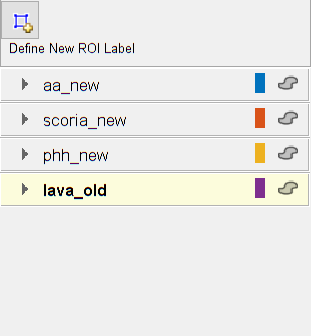

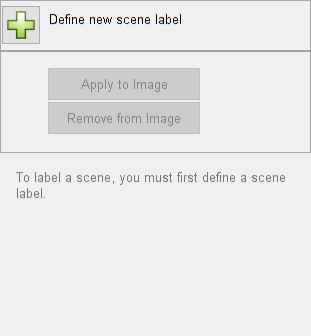

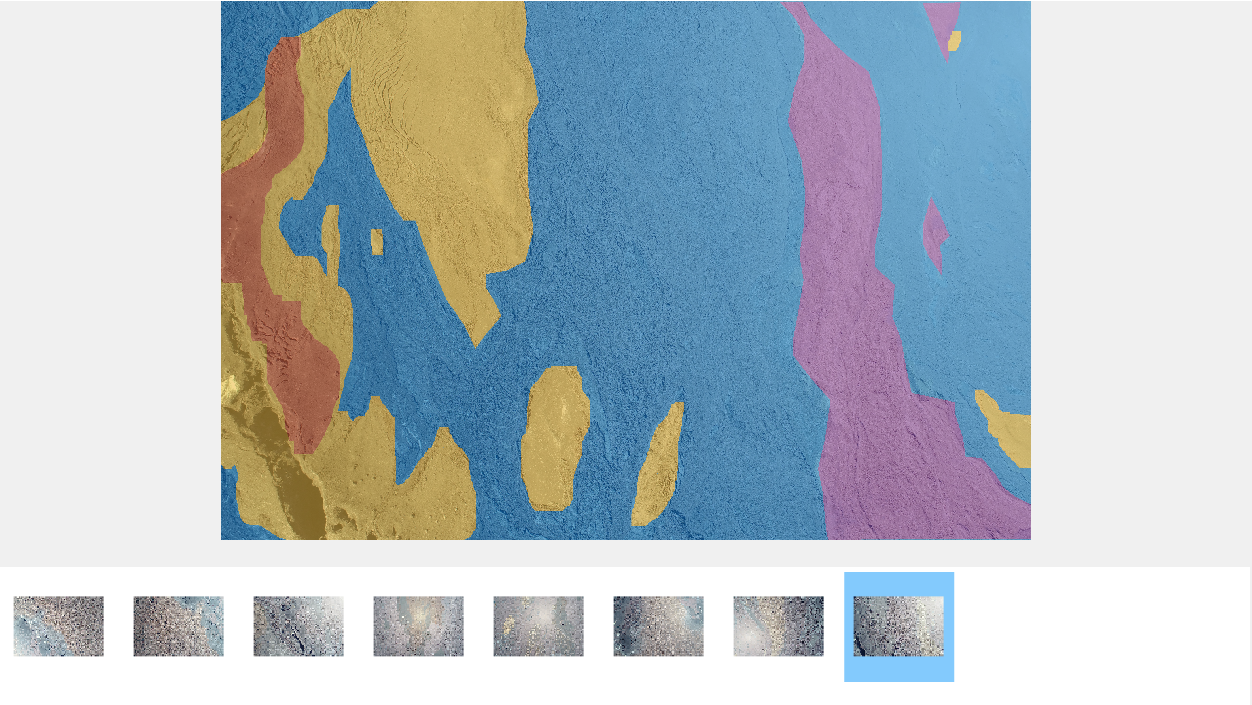

%   Open Image Labeler to create pixel labels and save session. 
%   Comment out once labels and session are saved. 

%imageLabeler(imds)

%   labels are stored in 'galLabels.mat'
%   session is stored in 'galLabelingSession.mat'
    
load galLabels.mat labelDefs;
galLabels = labelDefs;

load galLabelingSession.mat imageLabelingSession;
galLabelingSession = imageLabelingSession.FileName;

## Image Labeler

imageLabeler(galLabelingSession); %open image labeler, export ground truth

%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

% create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training

pximds = pixelLabelImageDatastore(imds,pxds);  %%%needs to be same number of files

%set training options

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',20,'VerboseFrequency',10);

## Create Segmentation Network

% Set classes to names of lava classes
classes = galLabels{1:4,"Name"};

numClasses = numel(classes);

%Set network image input size
imageSize = [64 64 3]; 

%create lgraph object from SegNet layers (uninitalized encoder depth)
lgraph = segnetLayers(imageSize,numClasses,5);

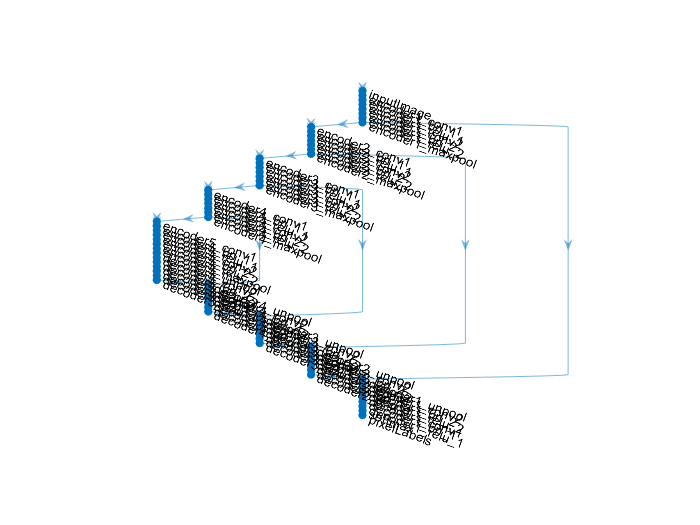

plot(lgraph)

hAxes = gca; 
axis off

## Train Network

% Train neural network using pixel image datastore and pre-defined
% architecture

net = trainNetwork(pximds,lgraph,options)

Undefined function or variable 'pximds'.

## Run trained network on test images

pxdsResults = semanticseg(testimds,net,'WriteLocation',tempdir);

## Evaluate Semantic Segmentation data set against ground truth

ssm = evaluateSemanticSegmentation(pxdsResults, pxdsTruth)

ssm.ClassMetrics

ssm.NormalizedConfusionMatrix